# ***TALLER 11: *****APLICACIÓN DE MÉTODOS NUMÉRICOS A UN MODELO (SIRV)**

# **INVASIÓN ZOOMBIE**

***Presentado por*****: ***Sara García Behaine*

*Ecuaciones diferenciales *

*Ingeniería Civil*

*Eafit  *

*13-Agosto-2023*

***OBJETIVO*** 

Resolver numéricamente la ecuación de estado de un modelo epidemiológico [SIRV](https://en.wikipedia.org/wiki/Compartmental_models_in_epidemiology#The_SIRV_model) (Susceptibles, Infectados, Recuperador y Vacunados) no lineal en un archivo Live Script de MATLAB y analizar el resultado.

***INTRODUCCIÓN : ***

Este modelo epidemiológico modelado a partir del software "Matlab", se centra en simular una población de zombies utilizando el modelo (SIRV) que representa a los susceptibles, infectados, recuperados y vacunados. Para llevar a cabo esta simulación, se empleará la función ode45 de Matlab junto con la implementación de una odeFunction. En este proyecto, se abordarán cinco ejercicios diferentes:

1. Resolución numérica de una ecuación diferencial no lineal y visualización de las soluciones.

2. Aumento de la cantidad inicial de infectados (i(0)).

3. Incremento del parámetro beta (β)  en la ecuación diferencial.

4. Incremento del parámetro gamma (γ) en la ecuación diferencial.

5. Incremento del parámetro delta (δ) en la ecuación diferencial.

Estos ejercicios permitirán explorar diversas situaciones y escenarios en la propagación de una infección zoombie, utilizando un modelo epidemiológico basado en el sistema SIRV y aprovechando las capacidades de Matlab para resolver ecuaciones diferenciales y graficar resultados.

**MÉTODOS A USAR:**

- *Usaré elementos teóricos dictados en clases, los usaré como ejemplo para la solución de la ecuación diferencial y de los otros 5 ejercicios mencionados anteriormente*

- *Método deductivo (mirar la parte teórica y a partir de lo que matlab arroje, analizarlo)*

- *En matlab, emplearé diversas funciones que me ayudarán a crear mis codigos y posteriormente a darles solución; primeramente ****(syms)****, la cuál me permitirá declarar las variables simbólicas de los diferentes ejercicios, OdeFunction (*resuelven problemas de valores iniciales con una gran variedad de propiedades), *ode45 (el cual nos ayuda a *comparar métodos de orden cuatro y cinco para estimar el error y determinar el tamaño del paso), h (es el paso del tiempo) tmin: (que es el tiempo minimo o inicial del sistema) tmax: (que es el tiempo maximo o final del sistema), tspan (que es el vector de elementos temporales iniciales y finales, o más bien, es el vector temporal del sistema), también usaré herramientas como (plot, grid on, title, x label, y label, legends, los cuales me serán de ayuda para hacer graficos y embellecerlos, para obtener información que me sea de ayuda en los diferentes gráficos)

#### **DESCRIPCIÓN DEL MODELO:**

Dada la siguiente la siguiente **ecuación de estado** de **cuarto orden no lineal** de un modelo SIRV (Susceptibles-Infectados-Recuperados-Vacunados) para cierta INVASIÓN ZOOMBIE, resolverla utilizando el método numérico de Runge-Kutta implementado en la función [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) de MATLAB.

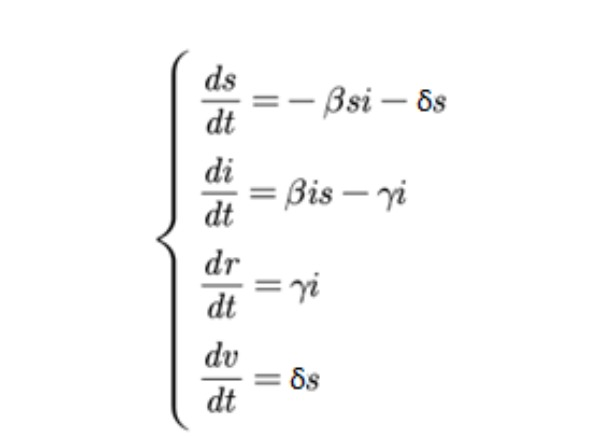

Supongamos que hay una enfermedad contagiosa entre zoombies, el cual queremos modelar por medio de un método numérico que nos ayudaá a saber lo siguiente: 

SUPUESTOS: Población cerrada (no llegan zoombies de otros lugares) y constante (*s* + *i* + *r* + *v* = 1), población uniforme, mezcla homogénea (sin consideraciones de edad, distribución espacial, educación o estructura social entre zoombies).

Donde, **S** es el porcentaje de **zoombies SUSCEPTIBLES, **(son los que pueden contraer la enfermedad) **I** es el porcentaje de **zoombies infectados,** **R** es el porcentaje de **zoombies recuperados,** (y que no vuelven a contraer la enfermedad, es decir, quedan inmunes) y **V** es el porcentaje de** zoombies vacunados.**

**β **es la tasa de transmisión, **γ** es la tasa de recuperación y aislamiento, y **δ **es la tasa de vacunación.

Observar que se tiene una epidemia creciente si (igual que en el caso SIR):

*R*0 es el número reproductivo básico.

Caso para estudiar (hay epidemia, *R*0 > 1): β = 0.1, γ = 0.02, δ = 0.001,

*s*(0) = 0.8, *i*(0) = 0.1, *r*(0) = 0, *v*(0) = 0.1

**Entregable 1:**

Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?

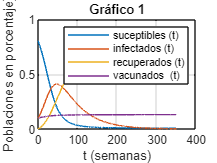

% Definimos las variables de estado
syms s(t) inf(t) r(t) v(t)

%Definimos las constantes 
beta = 0.1; % Tasa de contagio de zoombies 
gamma = 0.02; % Tasa de recuperación de zoombies 
delta = 0.001;  % Tasa de vacunación de zoombies 

% Ahora definimos la parte derecha de la ecuación de estado 
f1 = (-beta * s * inf) - delta * s; 
f2 = beta * s * inf - gamma * inf; 
f3 = gamma * inf;  
f4 = delta * s; %(Ésta ecuación es nueva comparada con la SIR)
f = odeFunction([f1 f2 f3 f4],[s inf r v]);

% Defino el paso en tiempo y tiempo final
h = 0.1; 
tmin = 0; 
tmax = 350;
tspan = tmin:h:tmax; % Vector temporal 

% Solución del modelo:
v0 = 0.1; ci = [0.9-v0 0.1 0 v0]; [t,x] = ode45(f,tspan,ci); 
plot(t,x), xlabel ('t (semanas)'), ylabel ('Poblaciones en porcentaje)'), grid
legend ({'suceptibles (t)','infectados (t)', 'recuperados (t)','vacunados  (t)'})
title ('Gráfico 1')

**Comparación de los infectados al cambiar la condición inicial v(0):**

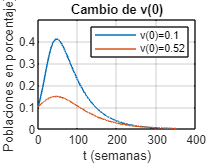

v0 = 0.1; ci = [0.9-v0 0.1 0 v0]; [t12,x1] = ode45(f,tspan,ci); %Definición de v(0), condiciones iniciales (ci) y vectores temporales,
%con ayuda del comando ode45, tspan (Para obtener soluciones en momentos
%específicos entre tiempo inicial y tiempo final)
v0 = 0.52; ci = [0.9-v0 0.1 0 v0]; [t13,x2] = ode45(f,tspan,ci);
%A continuación plotearé la función para un mejor análisis 
plot(t,x1(:,2),t,x2(:,2)), xlabel ('t (semanas)'), ylabel ('Poblaciones en porcentaje)'),
grid on %Activamos la cuadricula de la gráfica 
legend ({'v(0)=0.1','v(0)=0.52'}) %Ponemos nuestras leyendas 
title ('Cambio de v(0)') %Titulamos la gráfica 

**Entregable 2: **

Graficar sólo la solución *i*(*t*) con un aumento sólo de *i*(0) y usando al menos 5 valores. Observar que al cambiar *i*(0) cambia *s*(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.

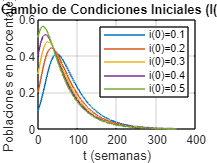

%A continuación definiré aumentos de i(0), conciciones iniciales del
%sistema e implementaré ode45, vectores temporales
i0 = 0.1; ci = [0.9-i0 i0 0 0.1]; [t1,x1] = ode45(f,tspan,ci); 
i0 = 0.2; ci = [0.9-i0 i0 0 0.1]; [t2,x2] = ode45(f,tspan,ci);
i0 = 0.3; ci = [0.9-i0 i0 0 0.1]; [t3,x3] = ode45(f,tspan,ci);
i0 = 0.4; ci = [0.9-i0 i0 0 0.1]; [t4,x4] = ode45(f,tspan,ci);
i0 = 0.5; ci = [0.9-i0 i0 0 0.1]; [t5,x5] = ode45(f,tspan,ci);

%Ploteamos nuestra funcion para visualizarlo de manera correcta y completa 
plot(t,x1(:,2),t,x2(:,2),t,x3(:,2),t,x4(:,2),t,x5(:,2)),
xlabel ('t (semanas)'), % Colocamos nombre al eje X
ylabel ('Poblaciones en porcentaje)'), % Colocamos nombre al eje Y
grid on %muestra las líneas de cuadrícula principales para los ejes actuales  
legend ({'i(0)=0.1','i(0)=0.2','i(0)=0.3','i(0)=0.4','i(0)=0.5'}) %Colocamos nuestras legendas 
title('Cambio de Condiciones Iniciales (I(0))') %Titulamos nuestro gráfico 

**Entregable 3: **

Graficar sólo la solución *i*(*t*) con un aumento sólo de** β** y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.

Comparación de los infectados al aumentar solo β:

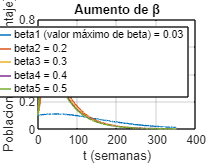

syms s(t) inf(t) r(t) v(t)  % Definimos las variables de estado
beta1 = 0.03;
beta2 = 0.2;
beta3= 0.3;
beta4 = 0.4; 
beta5 = 0.5; %tasa de contagio
gamma = 0.02; %tasa de recuperación 
delta = 0.001;  %tasa de vacunación 
% Ahora definimos la parte derecha de la ecuación de estado  
%con cada una de las constantes y de las variables simbólicas 
f1beta1 = (-beta1 * s * inf) - delta * s;  
f1beta2 = (-beta2 * s * inf) - delta * s; 
f1beta3 = (-beta3 * s * inf) - delta * s; 
f1beta4 = (-beta4 * s * inf) - delta * s; 
f1beta5 = (-beta5 * s * inf) - delta * s;  
f2beta1 = beta1 * s * inf - gamma * inf; 
f2beta2 = beta2 * s * inf - gamma * inf; 
f2beta3 = beta3 * s * inf - gamma * inf; 
f2beta4 = beta4 * s * inf - gamma * inf; 
f2beta5 = beta5 * s * inf - gamma * inf; 
f3 = gamma * inf;  
f4 = delta * s;
%Implementamos el comando odeFunction ya que 
% resuelven problemas de valores iniciales con una gran variedad de propiedades.
funcion1 = odeFunction([f1beta1 f2beta1 f3 f4],[s inf r v]); 
funcion2 = odeFunction([f1beta2 f2beta2 f3 f4],[s inf r v]);
funcion3 = odeFunction([f1beta3 f2beta3 f3 f4],[s inf r v]);
funcion4 = odeFunction([f1beta4 f2beta4 f3 f4],[s inf r v]);
funcion5 = odeFunction([f1beta5 f2beta5 f3 f4],[s inf r v]);
h = 0.1; %Paso del tiempo en 0.1 
tmin = 0; %Tiempo inicial o mínimo 
tmax = 350; %Tiempo final o máximo 
tspan = tmin:h:tmax;%Definimos nuestro vector temporal 
ci = [0.8 0.1 0 0.1]; %Definimos nuestras condiciones iniciales del sistema 
[tbeta1,xbeta1] = ode45(funcion1,tspan,ci); 
[tbeta2,xbeta2] = ode45(funcion2,tspan,ci); 
[tbeta3,xbeta3] = ode45(funcion3,tspan,ci); 
[tbeta4,xbeta4] = ode45(funcion4,tspan,ci); 
[tbeta5,xbeta5] = ode45(funcion5,tspan,ci); 
%Ahora graficamos para observar mas detenidamente lo que pasa
%con nuestro sistema 
plot(tbeta1,xbeta1(:,2),tbeta2,xbeta2(:,2),tbeta3,xbeta3(:,2),tbeta4,xbeta4(:,2),tbeta5,xbeta5(:,2)), %Ploteamos la funcion 
xlabel ('t (semanas)'), %Le ponemos nombre al eje x  
ylabel ('Poblaciones en porcentaje)'), %Le ponemos nombre al eje y 
grid on  %muestra las líneas de cuadrícula principales para los ejes actuales 
legend ({'beta1 (valor máximo de beta) = 0.03','beta2 = 0.2','beta3 = 0.3','beta4 = 0.4','beta5 = 0.5'}) %Colocamos nuestras leyendas 
title ('Aumento de β') %Ponemos titulo a nuestro gráfico 

**Entregable 4: **

Graficar sólo la solución *i*(*t*) con un aumento sólo de **γ** y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.

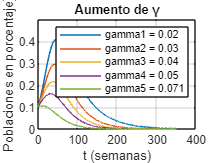

syms s(t) inf(t) r(t) v(t)  % Definimos nuestras variables de estado
beta = 0.1;  %tasa de contagio
gamma1 = 0.02;
gamma2 = 0.03;
gamma3 = 0.04; 
gamma4 = 0.05;
gamma5 = 0.071; %tasa de recuperación 
delta = 0.001;  %tasa de vacunación 
%Ahora definimos la parte derecha de la ecuación de estado  
%con cada una de las constantes y de las variables simbólicas 
f1 = (-beta * s * inf) - delta * s;  
f2gamma1 = beta * s * inf - gamma1 * inf; 
f2gamma2 = beta * s * inf - gamma2 * inf; 
f2gamma3 = beta * s * inf - gamma3 * inf; 
f2gamma4 = beta * s * inf - gamma4 * inf; 
f2gamma5 = beta * s * inf - gamma5 * inf; 
f3gamma1 = gamma1 * inf;  
f3gamma2 = gamma2 * inf;  
f3gamma3 = gamma3 * inf;  
f3gamma4 = gamma4 * inf;  
f3gamma5 = gamma5 * inf;  
f4 = delta * s; 
%Implementamos el comando odeFunction ya que 
% resuelven problemas de valores iniciales con una gran variedad de propiedades.
funcion1 = odeFunction([f1 f2gamma1 f3gamma1 f4],[s inf r v]);
funcion2 = odeFunction([f1 f2gamma2 f3gamma2 f4],[s inf r v]);
funcion3 = odeFunction([f1 f2gamma3 f3gamma3 f4],[s inf r v]);
funcion4 = odeFunction([f1 f2gamma4 f3gamma4 f4],[s inf r v]);
funcion5 = odeFunction([f1 f2gamma5 f3gamma5 f4],[s inf r v]);
h = 0.1; %Definimos nuestro paso del tiempo en 0.1 
tmin = 0; %Definimos nuestro tiempo inicial o mínimo 
tmax = 350;%Definimos nuestro tiempo final o máximo 
tspan = tmin:h:tmax; %Definimos el vector temporal del sistema 
ci = [0.8 0.1 0 0.1]; %Añadimos y definimos nuestras condiciones iniciales 
[tgamma1,xgamma1] = ode45(funcion1,tspan,ci); 
[tgamma2,xgamma2] = ode45(funcion2,tspan,ci); 
[tgamma3,xgamma3] = ode45(funcion3,tspan,ci); 
[tgamma4,xgamma4] = ode45(funcion4,tspan,ci); 
[tgamma5,xgamma5] = ode45(funcion5,tspan,ci); 
%Ploteamos nuestra funcion para entender el 
% comportamiento del sistema y poder visualizarlo 
plot(tgamma1,xgamma1(:,2),tgamma2,xgamma2(:,2),tgamma3,xgamma3(:,2),tgamma4,xgamma4(:,2),tgamma5,xgamma5(:,2)), 
xlabel ('t (semanas)'), %Damos nombre al eje x 
ylabel ('Poblaciones en porcentaje)'), %Damos nombre al eje Y 
grid on  %muestra las líneas de cuadrícula principales para los ejes actuales
legend ({'gamma1 = 0.02','gamma2 = 0.03','gamma3 = 0.04','gamma4 = 0.05','gamma5 = 0.071'}) %Ponemos nuestras leyendas 
title ('Aumento de γ') %Ponemos titulo a nuestro gráfico 

**Entregable 5: **

Graficar sólo la solución *i*(*t*) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.

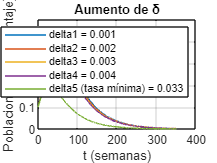

syms s(t) inf(t) r(t) v(t)  % Definimos nuestras variables de estado
beta = 0.1;  %tasa de contagio
gamma = 0.02; %tasa de recuperación 
delta1 = 0.001;
delta2 = 0.002; 
delta3 = 0.003; 
delta4 = 0.004; 
delta5 = 0.033;  %tasa de vacunación 
%Ahora definimos la parte derecha de la ecuación de estado  
%con cada una de las constantes y de las variables simbólicas
f1delta1 = (-beta * s * inf) - delta1 * s;  
f1delta2 = (-beta * s * inf) - delta2 * s;
f1delta3 = (-beta * s * inf) - delta3 * s;
f1delta4 = (-beta * s * inf) - delta4 * s;
f1delta5 = (-beta * s * inf) - delta5 * s;
f2 = beta * s * inf - gamma * inf; 
f3 = gamma * inf;   
f4delta1 = delta1 * s; 
f4delta2 = delta2 * s; 
f4delta3 = delta3 * s; 
f4delta4 = delta4 * s; 
f4delta5 = delta5 * s; 
%Implementamos el comando odeFunction ya que 
% resuelven problemas de valores iniciales con una gran variedad de propiedades.
funcion1 = odeFunction([f1delta1 f2 f3 f4delta1],[s inf r v]);
funcion2 = odeFunction([f1delta2 f2 f3 f4delta2],[s inf r v]);
funcion3 = odeFunction([f1delta3 f2 f3 f4delta3],[s inf r v]);
funcion4 = odeFunction([f1delta4 f2 f3 f4delta4],[s inf r v]);
funcion5 = odeFunction([f1delta5 f2 f3 f4delta5],[s inf r v]);
h = 0.1; %Definimos el paso del tiempo de nuestro sistema 
tmin = 0; %Definimos tiempo minimo o inicial 
tmax = 350; %Definimos tiempo final o maximo 
tspan = tmin:h:tmax; %Definimos nuestro vector temporal 
ci = [0.8 0.1 0 0.1]; %Definimos y añadimos nuestras condiciones iniciales del sistema 
[tdelta1,xdelta1] = ode45(funcion1,tspan,ci); 
[tdelta2,xdelta2] = ode45(funcion2,tspan,ci); 
[tdelta3,xdelta3] = ode45(funcion3,tspan,ci); 
[tdelta4,xdelta4] = ode45(funcion4,tspan,ci); 
[tdelta5,xdelta5] = ode45(funcion5,tspan,ci); 
%Ploteamos nuestra funcion para entender el 
% comportamiento del sistema y poder visualizarlo correctamente 
plot(tdelta1,xdelta1(:,2),tdelta2,xdelta2(:,2),tdelta3,xdelta3(:,2),tdelta4,xdelta4(:,2),tdelta5,xdelta5(:,2)),
xlabel ('t (semanas)'), %Damos nombre al eje x 
ylabel ('Poblaciones en porcentaje)'), %Damos nombre al eje Y 
grid on %muestra las líneas de cuadrícula principales para los ejes actuales
legend ({'delta1 = 0.001','delta2 = 0.002','delta3 = 0.003','delta4 = 0.004','delta5 (tasa mínima) = 0.033'}) %Leyendas de nuestra gráfica 
title ('Aumento de δ') %Titulamos nuestra gráfica 

**ANÁLISIS DE LOS 5 ENTREGABLES **

**ENTREGABLE 1:   **

Al aumentar la vacunacion en el sistema SIRV, disminuye el número de zoombies que sean susceptibles al virus o enfermedad, eventualmente se reduce la transmision de la enfermedad y tiene una relación directa con las zoombies infectadas, es decir, disminuye. Tambien podemos concluir que al aumentar la vacunacion el pico de los infectados va a disminuir con respecto al tiempo (tienen una relación inversamente proporcional). Y el porcentaje minimo de la poblacion que debe estar vacunada tiene que ser del 52%, para que el pico de infectados se incremente solo un 50% con respecto al porcentaje inicial de 10%. 

**ENTREGABLE 2:**

Primero que todo en esta tarea aumentamos el valor *i*(0) (zoombies infectados), lo primero que podemos observar es, que el pico de infectados aumenta y crece de forma mas rápida, tambien podemos concluir que el tiempo de la epidemia disminuye al subir más rapido al pico,  otra observacion que puedo hacer con respecto a la gráfica es que se va rodando mas al eje (y), se evidencia una relacion directamente proporcional al aumentar el valor de i(0) se va aumentar el valor del pico.

#### ENTREGABLE 3:

Podemos concluir de la grafica que al aumentar la tasa de contagio, la población de infectados aumenta exponecialmente y se alcance el pico en menos tiempo, es peligroso tener una tasa de contagio muy alta, por que puede subir la mortalidad del virus o de la enfermedad, la tasa de contagio puede ser manipulada y la forma mas efectiva de controlarla, es hacer cuarentenas o aislar a los zoombies para que no se sigan contagiando y aumente el tiempo para que suceda el pico, al aumentar el tiempo los sistemas de salud se pueden preparar de una mejor forma para atender a estos zoombies, vacunandolos tambien disminuye el numero de infectados, que en lugares donde sea muy concurrido por estos zoombies como el transporte publico, universidades, colegios, existan zonas de desinfeccion. La tasa de contagio si es una entrada del sistema SIRV. El valor maximo de beta es de 0.03 del cual se evitaria una epidemia.

#### ENTREGABLE 4:

Podemos concluir de la grafica que al aumentar la tasa de recuperacion, la poblacion de zoombies infectados disminuyen paulatiamente y el pico que llamabamos antes se suaviza, se puede concluir que la tasa de recuperacion y los infectados tienen una relacion inversamente proporcional, al disminuir los infectados, se disminuye la tasa de contagio y existirá más tiempo para los sistemas de salud de antender  a los zoombies y la mortalidad no sera tan alta, un buen manejo de las prevenciones ante la enfermedad ayudan a tener una tasa de recuperacion tan alta. El valor minimo de la tasa de recuperacion es de 0.071 para evitar una epidemia.

#### ENTREGABLE 5: 

Podemos concluir de la grafica que al aumentar la tasa de vacunacion, la poblacion de infectados disminuye, ésta es una de las formas mas eficientes para que la enfermedad no contagie a muchos zoombies y que su tasa de mortalidad sea baja, la población tambien adquire inmunidad al virus, este valor puede ser manipulado por entidades, gobiernos o personas que promuevan las jornadas de vacunacion o gobiernos que le den prioridad a que toda su poblacion se vacune para no poner en riesgo la salud de la poblacion, la tasa de vacunacion es una entrada al sistema que si se tiene que tener encuenta. la tasa minima que se debe vacunar es de 0.033 para que el pico de infectados incremente solo en un 100% con respecto al porcentaje inicial de 10%.